**Exercise 7**

**Part (i):**

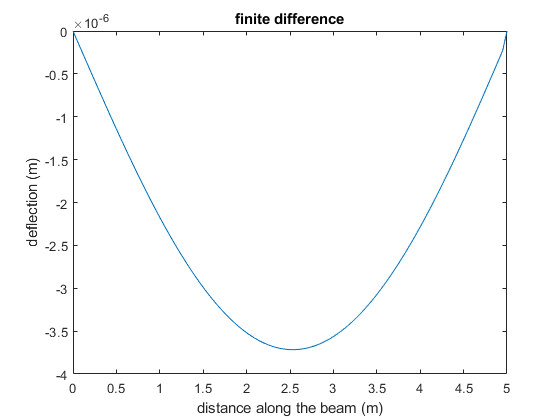

x = [0:0.05:5];
length(x);
h=1e-3;
n=2;
[result]=fda_heat(x);

plot(x,result)
title('finite difference');
xlabel('distance along the beam (m)')
ylabel('deflection (m)');

**Part (ii):**

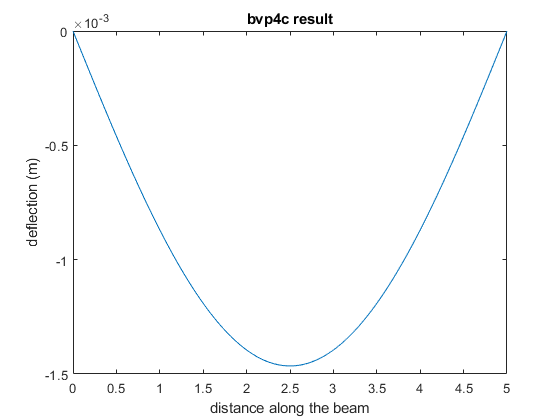


xinit = linspace(0,5); 
yinit=[0 100]; % 
% matlab solution
solinit = bvpinit(xinit,yinit);
[result2]=bvp4c(@deflec, @eqbc, solinit);
plot(result2.x,result2.y(1,:))
title('bvp4c result');
xlabel('distance along the beam');
ylabel('deflection (m)');

**part (iii):**

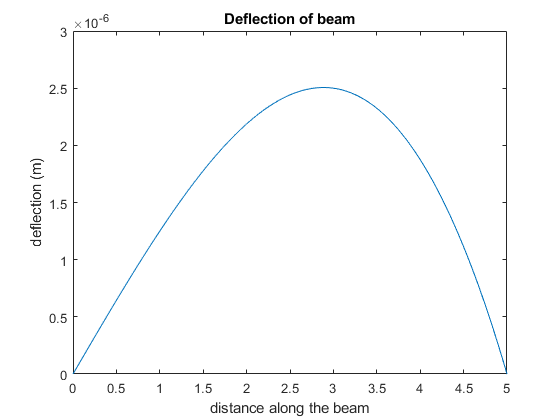

xinit = linspace(0,5); 
yinit=[0 100]; % 
% matlab solution
solinit = bvpinit(xinit,yinit);
[result3]=bvp4c(@partii, @eqbc, solinit);
plot(result3.x,result3.y(1,:))
title('Deflection of beam')
xlabel('distance along the beam');
ylabel('deflection (m)');

function [dydx]=partii(x,z)
L=5;q=1500;E=20*10^9;
h=10*10^(-2);w=5*10^(-2);
I=h*w^3/12;
dydx=zeros(2,1);
dydx(1) = z(2);
dydx(2) = (1/E*I)*(-q/2)*sqrt((1+z(2)^2)^3)*(x-L*x);
end

function [res] = eqbc(ya,yb) % initial condition
res = [ya(1); yb(1)];
end

function [g] = guess(x)
g = [sin(x); cos(x)];
end

function [dydx] = deflec(x,z)
L=5;q=1500;E=20*10^9;I=(5*10^(-2))*(10*10^(-2))/12;
const=-q/(2*E*I);
dydx=zeros(2,1);
dydx(1) = z(2);
dydx(2) = const*(x^2-L*x);
end

function [T] = fda_heat(x)
y0=0;yL=0;
L=5; q=1500; E=20*10^9; I=(5*10^(-2))*(10*10^(-2))/12;
const=-q/(2*E*I); dx=x(2)-x(1);

m=length(x);
n=m-2; % only solving for the interior points
ld=ones(n,1); %lower diagonal is = 1
ud=ones(n,1);% upped diagonal is 1

d=zeros(n,1); % to initialize the vector,diagonal
d(1:n)=-2;

b=zeros(n,1);% initializing
b(1)=dx^2*(const*(x(1)^2-L*x(1)))-y0; % output vector, y0 bc

b(n)= dx^2*const*(x(n)^2-L*x(n))-yL; %BC
for i=1:n-1
    b(i)=dx^2*const*dx^2*(x(i)^2-L*x(i));
end

%[ld d ud] marix nby3, n = size of matrix
A=my_spdiags([ld d ud],[-1,0,1]); % built in function that take the diagonals of matrix, use myspdiags instead
y=A\b;
T(2:m-1)=y;
T(1)=y0;
T(m)=yL;
end

function [A] = my_spdiags(A,id)
[n m] = size(A);
B = zeros(n,m);
for i=1:m
    if (id(i) <= 0)
        B(1:n+id(i),i) = A(-id(i)+1:n,i);
    else
        B(1+id(i):n,i) = A(1:n-id(i),i);
    end
end
% construct matrix
A = spdiags(B,id,n,n);
end